# Inital Notes

% N             - number of samples to take
% f             - frequency in hz
% scaler        - a scale value to be able to view only a portion of the wave
%                 to make analysis and overservations easier
% amplitude     - max height of the wave peak
% dc            - dc level of the signal
% sampleRate    - the frequency to sample at in hz

% Sinusiod :
% frequency, amplitude, sample rate, number of samples, scale, DC value

% LinCombo
% inWave1, scale1, inWave2, scale2, offset

## Section A

### Part 1

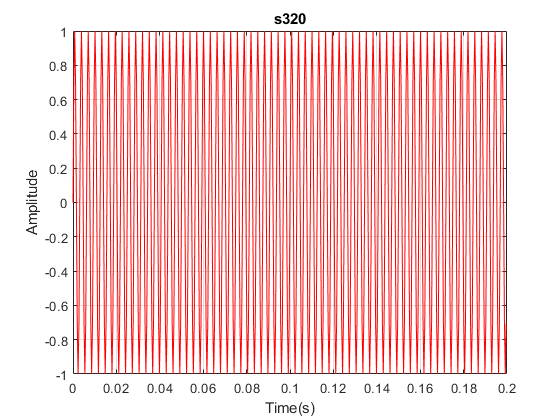

% inital values
N = 512;
f = 320;
scaler = 1;
amplitude = 1;
dc = 0;
sampleRate = 2560;

[s1, s320] = Sinusoid(f, amplitude, sampleRate, N, scaler, dc);

plot(s1, s320, 'r');
title('s320');
xlabel 'Time(s)';
ylabel 'Amplitude';
grid on;

#### Question 1:

The DC value of the wave is 0

#### Question 2:

Yes the sampling frequency is high enough to avoid aliasing since its more than twice nyquest. 

### Part 2

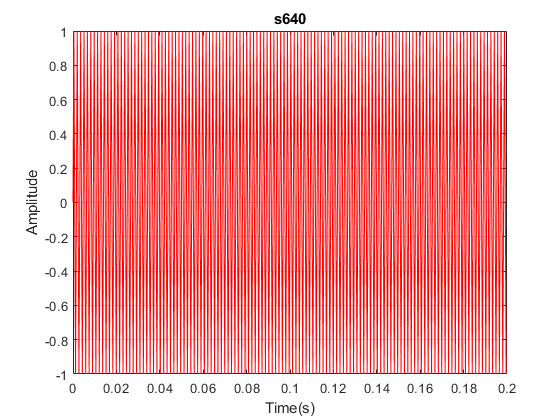

% inital values
N = 512;
f = 640;
scaler = 1;
amplitude = 1;
dc = 0;
sampleRate = 2560;

[s3, s640] = Sinusoid(f, amplitude, sampleRate, N, scaler, dc);

plot(s3, s640, 'r');
title('s640');
xlabel 'Time(s)';
ylabel 'Amplitude';
grid on;

#### Question 3:

Yes the sampling frequency is high enough to avoid aliasing since its more than twice nyquest.

## Section B

### Part 5

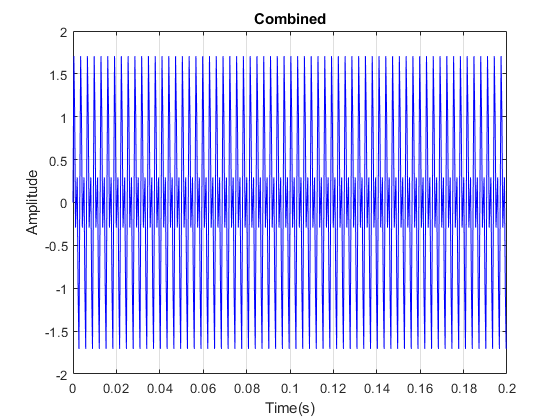

% adding waves 320 and 640
combined = LinCombo(s320, 1, s640, 1, 0);
plot(s1, combined, 'b');
title('Combined');
xlabel 'Time(s)';
ylabel 'Amplitude';
grid on;

## Section C

### Part 7

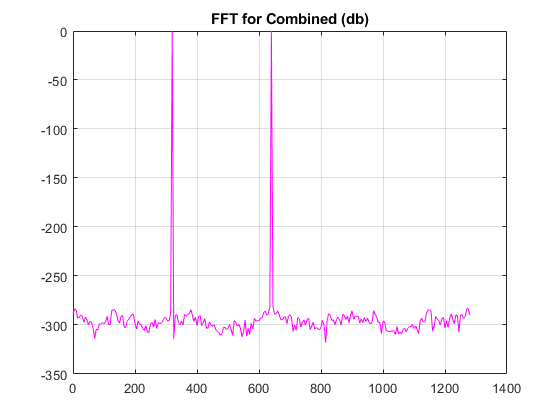

N = 512;                        % Number of samples

FFT = (fft(combined));          % FFt calculated

P2 = abs(FFT/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
dB = 20*log10(P1);              % Convert to dB

fD = 2560*(0:(N/2))/N;
plot(fD, dB, 'm');              % Plotting
title('FFT for Combined (db)');
grid on;

#### Question 4:

The range of frequencies that can be displayed is from 0 - nyquest, you can display further than that but it will be repeated. 

#### Question 5:

smaple frequency divided by number of samples

#### Question 6:

1280hz is the highest visible frequency because its the the nyquest frequency for the highest frequency signal (640hz)

### Part 9

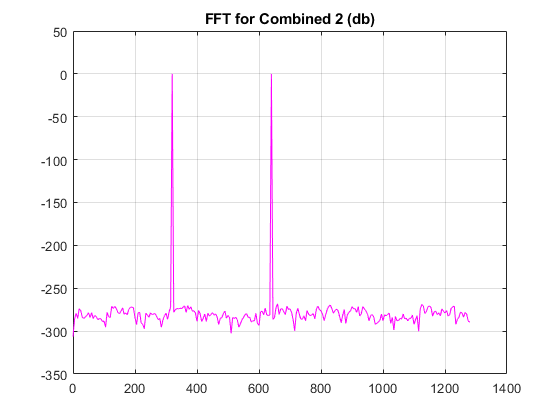

N = 512;                        % Number of samples

[timescale1, wave1] = Sinusoid(2880,1,2560,512,1,0);
[timescale2, wave2] = Sinusoid(3200,1,2560,512,1,0);

combined2 = LinCombo(wave1, 1, wave2, 1, 0);

FFT = (fft(combined2));          % FFt calculated

P4 = abs(FFT/N);
P3 = P4(1:N/2+1);
P3(2:end-1) = 2*P3(2:end-1);
dB2 = 20*log10(P3);              % Convert to dB

fD = 2560*(0:(N/2))/N;
plot(fD, dB2, 'm');              % Plotting
title('FFT for Combined 2 (db)');
grid on;

#### Question 7:

There is no visible difference between the two, however we know the bottom fft looks the sdame becasue the frequencies are multiples of the original set (320 and 640) so when sampled at the same speed they get alisiaed and look the same. 

## Section D

### Part 13

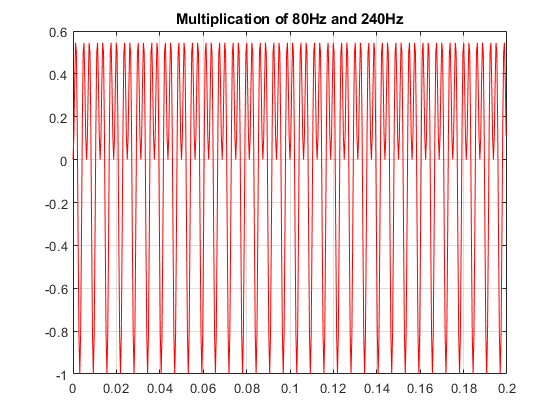

%generating a 80hz signal and a 240 hz signal
[timeScale1, s80] = Sinusoid(80,1,2560,512,1,0);
[timeScale2, s240] = Sinusoid(240,1,2560,512,1,0);

Multiplied = SigMult(s80, s240);

plot(timeScale1, Multiplied, 'r');
title('Multiplication of 80Hz and 240Hz');
grid on;

#### Question 8:

The frequencies that should be present should be 160Hz (240 - 80) and 320 (240 + 80)

#### Question 9:

No it should be the same. 

### Part 14

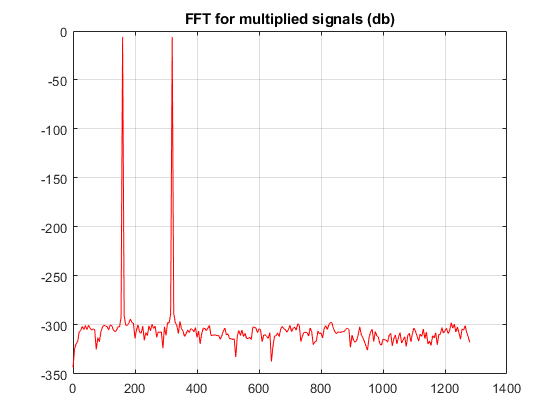

FFT = (fft(Multiplied));          % FFt calculated

P6 = abs(FFT/N);
P5 = P6(1:N/2+1);
P5(2:end-1) = 2*P5(2:end-1);
dB3 = 20*log10(P5);              % Convert to dB

fD = 2560*(0:(N/2))/N;
plot(fD, dB3, 'r');              % Plotting
title('FFT for multiplied signals (db)');
grid on;

#### Question 10:

Yes it looks exactly the way I expected it to since its functional components are the same. 

### part 15

IFFT = (ifft(FFT));          % FFt calculated 

mag = db2mag(IFFT);

dT = 1/2560;                        %sample rate
T = (N-1)/2560;                         %total time
timeScale = 0:dT:T

timeScale =          0    0.0004    0.0008    0.0012    0.0016    0.0020    0.0023    0.0027    0.0031    0.0035    0.0039    0.0043    0.0047    0.0051    0.0055    0.0059    0.0063    0.0066    0.0070    0.0074    0.0078    0.0082    0.0086    0.0090    0.0094    0.0098    0.0102    0.0105    0.0109    0.0113    0.0117    0.0121    0.0125    0.0129    0.0133    0.0137    0.0141    0.0145    0.0148    0.0152    0.0156    0.0160    0.0164    0.0168    0.0172    0.0176    0.0180    0.0184    0.0188    0.0191


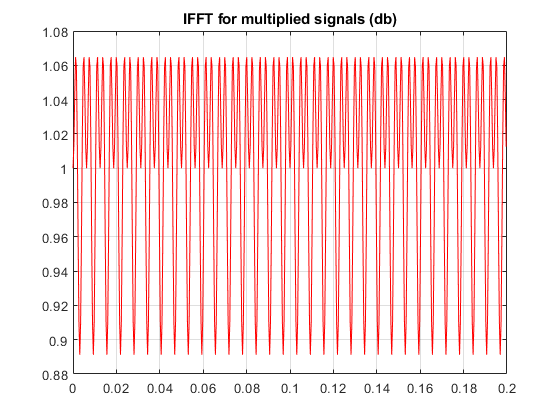



plot(timeScale, mag, 'r');              % Plotting
title('IFFT for multiplied signals (db)');
grid on;

#### Question 11:

They look exactly the same which is to be expected since both signals should be the same. 

## Section E

### Part 16

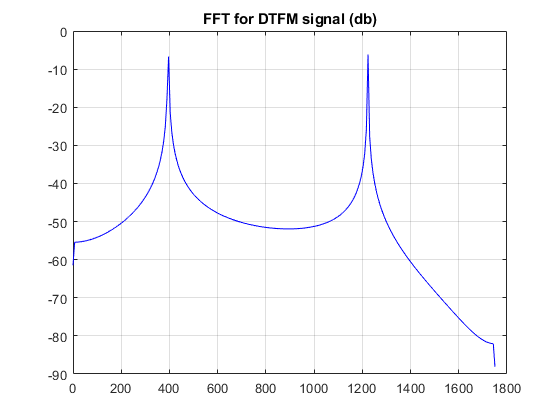

% Student number: 8409427
% number being used is the 3rd number in my student number so 0
% frequencies are: 1336 and 941 as described here: 
% https://en.wikipedia.org/wiki/Dual-tone_multi-frequency_signaling

[timeScale3, s1336] = Sinusoid(1336,1,3500,512,1,0);
[timeScale4, s941] = Sinusoid(941,1,3500,512,1,0);


Multiplied2 = SigMult(s1336, s941);

FFT = (fft(Multiplied2));          % FFt calculated

P8 = abs(FFT/N);
P7 = P8(1:N/2+1);
P7(2:end-1) = 2*P7(2:end-1);
dB4 = 20*log10(P7);              % Convert to dB

fD = 3500*(0:(N/2))/N;
plot(fD, dB4, 'b');              % Plotting
title('FFT for DTFM signal (db)');
grid on;

#### Question 12:

Yes the singal looks different that the previous ones, due to the spectral leakage.  